# Tecta-cre;Cx26flfl P21 Hair cells, and other ages

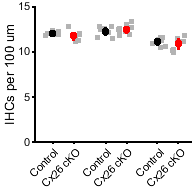

% plotting, raw data in excel document

conIHCapex21 = [11.82414895,11.89481502,12.15925145,11.94704835,11.96520726,11.92336903,11.76266307,12.1275168,12.34425663];
conIHCmid21 = [12.4587485,12.77597331,11.52937107,12.51444486,12.69767979,11.46876673,12.0753849];
conIHCbase21 = [11.23310261,10.81276959,10.44289477,11.31520386,10.49923881,11.52168124,11.51308744];

ckoIHCapex21 = [11.79442102,11.91396375,11.10195687,11.5462427,11.80469666,11.19869061,11.54274567,12.69610955];
ckoIHCmid21 = [12.40791004,12.20217257,12.50596214,11.89064091,12.39135948,11.77347828,12.95836621,12.31703475,12.62614231,13.26114657];
ckoIHCbase21 = [11.05280916,11.46563104,11.09181395,10.08108462,9.910456114,10.19575856,11.27676062,11.80097228];

conOHCapex21 = [38.93317337,37.71526714,40.82034416,37.88088501,40.5776594,36.5477181,38.08862326,38.53855338,43.89069024];
conOHCmid21 = [39.11467554,46.43574914,41.21750159,39.1409233,40.11312478,40.0132528,39.38875552];
conOHCbase21 = [33.02532166,37.11410102,35.67989047,35.68641218,36.86937998,35.69741194,36.68123206];

ckoOHCapex21 = [38.49877049,39.22890502,38.27253551,36.64677032,39.17012982,33.88321776,41.26531578,37.57012009];
ckoOHCmid21 = [44.46167765,38.93074105,35.48203213,33.93182893,40.05578993,33.91883028,38.58713493,37.52398957,39.30780153,39.20686812];
ckoOHCbase21 = [31.41324708,24.40121477,30.94032312,19.34478399,20.98684824,18.69222403,23.13181666,28.49503064]; 

%Cre+ Control
conCreIHCapex21 = [11.52973731];
conCreIHCmid21 = [12.80001743];
conCreIHCbase21 =[11.35245591];

conCreOHCapex21 = [43.53064087];
conCreOHCmid21 =[41.66814185];
conCreOHCbase21 =[33.76627913];

ylbl = ('IHCs per 100 um');
ylbl2 = ('OHCs per 100 um');
dim = [2 2];
conditions = {'Control','Cx26 cKO','Control','Cx26 cKO','Control','Cx26 cKO'};
compare6(conIHCapex21,ckoIHCapex21,conIHCmid21,ckoIHCmid21,conIHCbase21,ckoIHCbase21,conditions,ylbl,dim);
ylim([0 15])

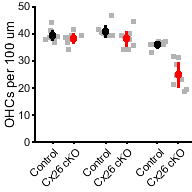


figure
compare6(conOHCapex21,ckoOHCapex21,conOHCmid21,ckoOHCmid21,conOHCbase21,ckoOHCbase21,conditions,ylbl2,dim);
ylim([0 50])


% better stats
geno = {'con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko',}';
mouse = [1 1 1 2 2 2 3 3 3 4 4 4 5 5 5 6 6 ]';
location = {'apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','middle','base'}'; 
SGNs = [conapex(1),conmid(1),conbase(1),conapex(2),conmid(2),conbase(2),conapex(3),conmid(3),conbase(3),ckoapex(1),ckomid(1),ckobase(1),ckoapex(2),ckomid(2),ckobase(2),ckomid(3),ckobase(3)]';


tbl = table(geno,mouse,location,SGNs,'VariableNames',{'Genotype','Mouse','Location','SGNs'})

lme = fitlme(tbl,'SGNs~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')
[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')


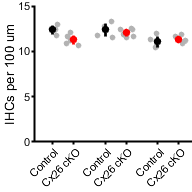

% P21 with GCaMP6s hair cells
conIHCapex21g6 = [11.76129495,12.93433212,12.4048616];
conIHCmid21g6 = [13.33287244,12.74309628,11.57404058,11.79865341];
conIHCbase21g6 = [11.30388992,11.96072975,10.5089545,10.47455556];

ckoIHCapex21g6 = [11.14167931,10.90205934,11.59655582,12.09050607,10.67491424];
ckoIHCmid21g6 = [12.50559844,11.54434471,11.6739768,12.3949835,12.41242744,11.89957916];
ckoIHCbase21g6 = [11.24711793,11.16348301,10.90256919,11.82947096,11.0613351,11.59134275];

conOHCapex21g6 = [39.66018063,42.10537903,38.86856636];
conOHCmid21g6 = [41.23314256,41.41506292,39.06238697,37.70439243];
conOHCbase21g6 = [35.01448828,34.66170663,34.73793295,34.04230557];

ckoOHCapex21g6 = [39.71008779,38.44410399,37.10897863,33.96856468,30.58218674];
ckoOHCmid21g6 = [40.13424615,35.21025138,38.59559677,38.9202482,30.88673804,36.5694384];
ckoOHCbase21g6 = [13.82458245,31.75390722,28.89180835,28.27532084,13.681125,15.75233759]; 

ylbl = ('IHCs per 100 um');
ylbl2 = ('OHCs per 100 um');
dim = [2 2];
conditions = {'Control','Cx26 cKO','Control','Cx26 cKO','Control','Cx26 cKO'};
compare6(conIHCapex21g6,ckoIHCapex21g6,conIHCmid21g6,ckoIHCmid21g6,conIHCbase21g6,ckoIHCbase21g6,conditions,ylbl,dim);
ylim([0 15])

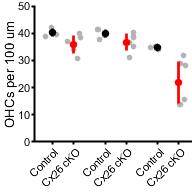

h = 1

p = 0.0412

h = 0

p = 0.4765

h = 0

p = 0.4955

h = 0

p = 0.1158

h = 0

p = 0.1292

h = 1

p = 0.0194


figure
compare6(conOHCapex21g6,ckoOHCapex21g6,conOHCmid21g6,ckoOHCmid21g6,conOHCbase21g6,ckoOHCbase21g6,conditions,ylbl2,dim);
ylim([0 50])

% better test? 


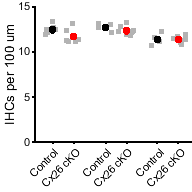

% P15/P16

conapex = [11.88777936,12.39996073,13.29554005,12.0945622,12.65093265,12.40608879];
conmid = [NaN,NaN,12.933075,12.58740223,12.11799316,13.04722225];
conbase = [11.47421171,NaN,11.27320763,11.06127071,12.1800306,10.66185516];

ckoapex = [NaN,11.02944073,12.25318583,11.18526528,11.04009297,NaN,13.08394368,11.33529812];
ckomid = [11.84326801,12.69525431,12.15428796,12.22600646,11.69574737,12.09632128,12.16034281,12.31163908,13.16626257];
ckobase = [10.77194055,NaN,11.36403371,11.81378521,11.01695161,11.63578819,11.314748,11.24862556,NaN];

conOHCapex16 = [39.34288884,38.49154478,42.71545847,39.95525012,42.87260511,37.79529376];
conOHCmid16 = [44.65571178,42.94525467,41.5105723,40.0114815];
conOHCbase16 = [40.15974098,37.57735877,36.67684498,40.68130219,33.8992318];

ckoOHCapex16 = [37.55261962,38.5100126,39.00502763,39.80244044,39.54258533,42.03506386];
ckoOHCmid16 = [39.17388651,40.67663115,38.36941886,41.33554566,42.15908936,39.16904033,38.79728419,38.08018599,46.70296912];
ckoOHCbase16 = [34.06262282,29.13854797,35.81053642,29.86173726,33.16199635,36.25862428,29.80885773];

ylbl = ('IHCs per 100 um');
ylbl2 = ('OHCs per 100 um');
dim = [2 2];
conditions = {'Control','Cx26 cKO','Control','Cx26 cKO','Control','Cx26 cKO'};
compare6(conapex,ckoapex,conmid,ckomid,conbase,ckobase,conditions,ylbl,dim);
ylim([0 15])

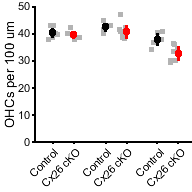


figure
compare6(conOHCapex16,ckoOHCapex16,conOHCmid16,ckoOHCmid16,conOHCbase16,ckoOHCbase16,conditions,ylbl2,dim);
ylim([0 50])


% better stats
geno = {'con','con','con','con','con','con','con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko',}';
mouse = [1 1 2 3 3 3 4 4 4 5 5 5 6 6 6 7 7 8 8 9 9 9 10 10 10 11 11 11 12 12 13 13 13 14 14 14 15]';
location = {'apex','base','apex','apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','middle','base','apex','middle','apex','middle','base','apex','middle','base','apex','middle','base','middle','base','apex','middle','base','apex','middle','base','middle',}'; 
SGNs = [conapex(1),conbase(1),conapex(2),conapex(3),conmid(3),conbase(3),conapex(4),conmid(4),conbase(4),conapex(5),conmid(5),conbase(5),conapex(6),conmid(6),conbase(6),ckomid(1),ckobase(1),ckoapex(2),ckomid(2),ckoapex(3),ckomid(3),ckobase(3),ckoapex(4),ckomid(4),ckobase(4),ckoapex(5),ckomid(5),ckobase(5),ckomid(6),ckobase(6),ckoapex(7),ckomid(7),ckobase(7),ckoapex(8),ckomid(8),ckobase(8),ckomid(9)]';

tbl = table(geno,mouse,location,SGNs,'VariableNames',{'Genotype','Mouse','Location','SGNs'})

tbl = 37×4 table
    Genotype    Mouse     Location      SGNs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }    11.888
    {'con'}       1      {'base'  }    11.474
    {'con'}       2      {'apex'  }      12.4
    {'con'}       3      {'apex'  }    13.296
    {'con'}       3      {'middle'}    12.933
    {'con'}       3      {'base'  }    11.273
    {'con'}       4      {'apex'  }    12.095
    {'con'}       4      {'middle'}    12.587
    {'con'}       4      {'base'  }    11.061
    {'con'}       5      {'apex'  }    12.651
    {'con'}       5      {'middle'}    12.118
    {'con'}       5      {'base'  }     12.18
    {'con'}       6      {'apex'  }    12.406
    {'con'}       6      {'middle'}    13.047
    {'con'}       6      {'base'  }    10.662
    {'cko'}       7      {'middle'}    11.843



lme = fitlme(tbl,'SGNs~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              37
    Fixed effects coefficients           2
    Random effects coefficients         18
    Covariance parameters                3

Formula:
    SGNs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    77.355    85.132    -33.678          67.355  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF    pValue        Lower       Upper    
    {'(Intercept)' }         12.164     0.34319     35.443    35    5.1428e-29      11.467        12.86
    {'Genotype_cko'}        -0.4095     0.18358    -2.2306    35      0.032212    -0.78219    -0.036815

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2              

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    12.1636
   -0.4095


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE         tStat      DF        pValue        Lower       Upper    
    {'(Intercept)' }         12.164     0.34319     35.443    2.4685    0.00020956      10.926       13.402
    {'Genotype_cko'}        -0.4095     0.18358    -2.2306    33.133       0.03259    -0.78295    -0.036063


h = 0

p = 0.0703

h = 0

p = 0.1444

h = 0

p = 0.9386

h = 0

p = 0.4793

h = 0

p = 0.2659

h = 1

p = 0.0117


% P7 
conIHCapex7 = [12.25813014,12.5347621];
conIHCmid7 = [13.01051828];
conIHCbase7 = [11.92916246,11.70269425];

ckoIHCapex7 = [13.53256883,13.67543252];
ckoIHCmid7 = [13.8099886,15.62679057];
ckoIHCbase7 = [11.24689867,12.99299559];

conOHCapex7 = [42.51223857,42.26838383];
conOHCmid7 = [43.07927164];
conOHCbase7 = [43.59566646,40.12352313];

ckoOHCapex7 = [46.01073403,48.3004638];
ckoOHCmid7 = [49.38826432,49.79737262];
ckoOHCbase7 = [38.68933142,41.04605426];



% P28

conIHCapex28 = [12.31040544,12.17157236];
conIHCmid28 = [11.89823239,12.17842076];
conIHCbase28 = [11.79129975];

ckoIHCapex28 = [11.95487887,11.85971976];
ckoIHCmid28 = [12.08642638,13.30225618];
ckoIHCbase28 = [11.89001114];

conOHCapex28 = [38.64894732,40.96202235];
conOHCmid28 = [39.75750822,42.50958189];
conOHCbase28 = [36.52426995];

ckoOHCapex28 = [38.99567632,31.81876034];
ckoOHCmid28 = [39.35115566,39.32840957];
ckoOHCbase28 = [39.73766881];

% P35
conIHCapex35 = [12.19763656,12.08358388];
conIHCmid35 = [12.50034723,12.38068419];
conIHCbase35 = [10.59228529,9.736705241];

ckoIHCapex35 = [11.81464266,11.84588504];
ckoIHCmid35 = [12.28697809,12.96871082];
ckoIHCbase35 = [9.708947334];

conOHCapex35 = [38.62584912,40.5663173];
conOHCmid35 = [39.5844329,37.87032811];
conOHCbase35 = [33.29003947,34.9096505];

ckoOHCapex35 = [34.86760396,33.63385215];
ckoOHCmid35 = [37.14667794,35.15961601];
ckoOHCbase35 = [16.61308766];

% P42
conIHCapex42 = [11.86406206,11.93837848,11.36930978,12.23948401];
conIHCmid42 = [12.72952106,11.88395463,12.39276813,12.53803858];
conIHCbase42 = [12.26904909,11.07227927,10.51669701,11.05856675];

ckoIHCapex42 = [11.98914126,11.16311021,11.82506972,11.21612558,11.61760648,12.17576392];
ckoIHCmid42 = [12.05187125,11.71642731,11.85731094,11.76332196,10.69098432];
ckoIHCbase42 = [7.290428229,10.73976526,5.401241148];

conOHCapex42 = [43.34014508,43.61162749,43.99428569,37.85700867];
conOHCmid42 = [41.04621076,39.70979962,40.62073999,39.4425797];
conOHCbase42 = [34.8552531,35.77197918,34.35454356,35.21280466];

ckoOHCapex42 = [36.82379102,33.77556424,34.8983765,39.82869085,37.17634074,37.88015441];
ckoOHCmid42 = [12.58750998,34.85637125,40.58848746,28.40411888,28.02771565];
ckoOHCbase42 = [1.402005429,17.38819137,8.243999647];

conCreIHCapex42 = [11.22030934,11.67169198]

conCreIHCapex42 =    11.2203   11.6717


conCreIHCmid42 = [11.52561712,11.96678488]

conCreIHCmid42 =    11.5256   11.9668


conCreIHCbase42 = [10.51727891,10.20766371]

conCreIHCbase42 =    10.5173   10.2077



conCreOHCapex42 = [34.52402872,35.01507594]

conCreOHCapex42 =    34.5240   35.0151


conCreOHCmid42 = [37.45825566,35.31660902]

conCreOHCmid42 =    37.4583   35.3166


conCreOHCbase42 = [31.30724885,28.88021929]

conCreOHCbase42 =    31.3072   28.8802



% P50
conIHCapex50 = [12.15495835,11.17353718,11.85334235];
conIHCmid50 = [13.64772894,13.13002723,12.38757555,12.32342396];
conIHCbase50 = [11.73273762,11.27086193,11.34555356];

ckoIHCapex50 = [12.17121533,11.55394827];
ckoIHCmid50 = [11.95188312,12.01309427];
ckoIHCbase50 = [5.079576179,11.70642569,6.430437404,1.457973902];

conOHCapex50 = [37.62249015,43.96543976,34.69270933];
conOHCmid50 = [45.32076026,40.81725856,39.46739187,39.83618444];
conOHCbase50 = [28.1585703,36.12455747,31.70936765];

ckoOHCapex50 = [36.77260803,36.10608835];
ckoOHCmid50 = [37.96480522,24.25720959];
ckoOHCbase50 = [12.92983027,14.27612888,2.679348918,0.48599130];

% P75
conIHCapex75 = [11.50278395,11.90342504,11.25710957];
conIHCmid75 = [12.58932261,12.77357959];
conIHCbase75 =[11.33113031,10.81370267];

ckoIHCapex75 =[11.85608296,12.02039887];
ckoIHCmid75 =[7.244172064,11.31660242];
ckoIHCbase75 =[7.575316124,2.966735478];

conOHCapex75 =[38.06873735,40.65131948,41.08844992];
conOHCmid75 =[35.85220135,39.48197329];
conOHCbase75 =[27.74970689,29.59539678];

ckoOHCapex75 =[36.0951859,32.73640544];
ckoOHCmid75 =[33.03342461,38.04304643];
ckoOHCbase75 =[0,0];

% P100
conIHCapex100 = [11.62470401,11.93825328,11.71264594,11.65176423,12.34737927];
conIHCmid100 = [12.9616508,12.45016316,12.31321536,11.73794206,13.0317828];
conIHCbase100 = [10.54698081,10.88725549,11.25407043,10.89205969,10.7838394];

ckoIHCapex100 = [12.1887869,11.25018954,6.240780665,11.45869142];
ckoIHCmid100 = [11.61571723,11.92587687,3.510886674,11.20673554,0.84088259];
ckoIHCbase100 = [0.262370782,0,0,0.259385878,0.712744828];

conOHCapex100 = [36.64308873,36.33381432,37.42333216,40.27457636,37.99193621];
conOHCmid100 = [39.46102576,39.37726021,41.31767822,38.00857429,42.78358881];
conOHCbase100 = [38.8320657,27.91603972,28.86913718,18.67210232,31.18569771];

ckoOHCapex100 = [35.11531463,32.2831526,5.106093271,35.49399537];
ckoOHCmid100 = [35.71833047,40.85247183,0.585147779,35.91902415,1.401470984];
ckoOHCbase100 = [0,0,0,0.518771756,0.237581609];

% P180 
conIHCapex180 = [12.58521238,12.27232284];
conIHCmid180 = [11.78536832,11.55543358];
conIHCbase180 = [5.808280284,1.162061031];

ckoIHCapex180 = [11.83124529,6.796073276,11.14782589];
ckoIHCmid180 = [0.276878691,0,3.007971123];
ckoIHCbase180 = [0.580415055,0,0];

conOHCapex180 = [38.5422129,38.86235567];
conOHCmid180 = [29.89459282,25.99972556];
conOHCbase180 = [2.555643325,0];

ckoOHCapex180 = [26.49170141,5.155641795,30.87090246];
ckoOHCmid180 = [0,0,0];
ckoOHCbase180 = [0,0,0];

agesApexCon = [7,7,16,16,16,16,16,16,21,21,21,21,21,21,21,28,28,35,35,42,42,42,42,50,50,50,75,75,75,100,100,100,100,100,120,120];
agesMidCon = [7,16,16,16,16,21,21,21,21,21,28,28,35,35,42,42,42,42,50,50,50,50,75,75,100,100,100,100,100,120,120];
agesBaseCon = [7,7,16,16,16,16,16,21,21,21,21,21,21,28,35,35,42,42,42,42,50,50,50,75,75,100,100,100,100,100,120,120];

agesApexConCre = [21,42,42];
agesMidConCre = [21,42,42]

agesMidConCre =     21    42    42


agesBaseConCre = [21,42,42]

agesBaseConCre =     21    42    42


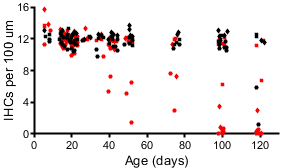


IHCcountsApexConCre = [conCreIHCapex21,conCreIHCapex42];
IHCcountsMidConCre = [conCreIHCmid21,conCreIHCmid42];
IHCcountsBaseConCre = [conCreIHCbase21,conCreIHCbase42];

IHCcountsApexCon = [conIHCapex7,conIHCapex16,conIHCapex21,conIHCapex28,conIHCapex35,conIHCapex42,conIHCapex50,conIHCapex75,conIHCapex100,conIHCapex180];
IHCcountsMidCon = [conIHCmid7,conIHCmid16,conIHCmid21,conIHCmid28,conIHCmid35,conIHCmid42,conIHCmid50,conIHCmid75,conIHCmid100,conIHCmid180];
IHCcountsBaseCon = [conIHCbase7,conIHCbase16,conIHCbase21,conIHCbase28,conIHCbase35,conIHCbase42,conIHCbase50,conIHCbase75,conIHCbase100,conIHCbase180];

agesApexCko = [7,7,16,16,16,16,16,16,21,21,21,21,21,21,28,28,35,35,42,42,42,42,42,42,50,50,75,75,100,100,100,100,120,120,120];
agesMidCko = [7,7,16,16,16,16,16,16,16,16,16,21,21,21,21,21,21,21,21,28,28,35,35,42,42,42,42,42,50,50,75,75,100,100,100,100,100,120,120,120];
agesBaseCko = [7,7,16,16,16,16,16,16,16,21,21,21,21,21,21,28,35,42,42,42,50,50,50,50,75,75,100,100,100,100,100,120,120,120];

IHCcountsApexCko = [ckoIHCapex7,ckoIHCapex16,ckoIHCapex21,ckoIHCapex28,ckoIHCapex35,ckoIHCapex42,ckoIHCapex50,ckoIHCapex75,ckoIHCapex100,ckoIHCapex180];
IHCcountsMidCko = [ckoIHCmid7,ckoIHCmid16,ckoIHCmid21,ckoIHCmid28,conIHCmid35,ckoIHCmid42,ckoIHCmid50,ckoIHCmid75,ckoIHCmid100,ckoIHCmid180];
IHCcountsBaseCko = [ckoIHCbase7,ckoIHCbase16,ckoIHCbase21,ckoIHCbase28,ckoIHCbase35,ckoIHCbase42,ckoIHCbase50,ckoIHCbase75,ckoIHCbase100,ckoIHCbase180];

% Scatter plot of all IHC loss across age
figure
% ages, counts
scatter(agesApexCko,IHCcountsApexCko,20,'r','square','filled','jitter','on', 'jitterAmount',2.5);
hold on
scatter(agesMidCko,IHCcountsMidCko,20,'r','diamond','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesBaseCko,IHCcountsBaseCko,20,'r','o','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesApexCon,IHCcountsApexCon,20,'k','square','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesMidCon,IHCcountsMidCon,20,'k','diamond','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesBaseCon,IHCcountsBaseCon,20,'k','o','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesApexConCre,IHCcountsApexConCre,12,'b','square','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesMidConCre,IHCcountsMidConCre,12,'b','diamond','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesBaseConCre,IHCcountsBaseConCre,12,'b','o','filled','jitter','on', 'jitterAmount',2.5);
ylbl = ('IHCs per 100 um');
ylabel(ylbl);
xlabel('Age (days)');
figQuality(gcf,gca,[3 1.75])
ylim([0 16])
xlim([0 130])
yticks([0 4 8 12 16]);

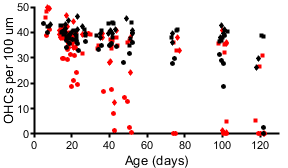

% OHCs 

OHCcountsApexCon = [conOHCapex7,conOHCapex16,conOHCapex21,conOHCapex28,conOHCapex35,conOHCapex42,conOHCapex50,conOHCapex75,conOHCapex100,conOHCapex180];
OHCcountsMidCon = [conOHCmid7,conOHCmid16,conOHCmid21,conOHCmid28,conOHCmid35,conOHCmid42,conOHCmid50,conOHCmid75,conOHCmid100,conOHCmid180];
OHCcountsBaseCon = [conOHCbase7,conOHCbase16,conOHCbase21,conOHCbase28,conOHCbase35,conOHCbase42,conOHCbase50,conOHCbase75,conOHCbase100,conOHCbase180];

OHCcountsApexCko = [ckoOHCapex7,ckoOHCapex16,ckoOHCapex21,ckoOHCapex28,ckoOHCapex35,ckoOHCapex42,ckoOHCapex50,ckoOHCapex75,ckoOHCapex100,ckoOHCapex180];
OHCcountsMidCko = [ckoOHCmid7,ckoOHCmid16,ckoOHCmid21,ckoOHCmid28,conOHCmid35,ckoOHCmid42,ckoOHCmid50,ckoOHCmid75,ckoOHCmid100,ckoOHCmid180];
OHCcountsBaseCko = [ckoOHCbase7,ckoOHCbase16,ckoOHCbase21,ckoOHCbase28,ckoOHCbase35,ckoOHCbase42,ckoOHCbase50,ckoOHCbase75,ckoOHCbase100,ckoOHCbase180];

OHCcountsApexConCre = [conCreOHCapex21,conCreOHCapex42];
OHCcountsMidConCre = [conCreOHCmid21,conCreOHCmid42];
OHCcountsBaseConCre = [conCreOHCbase21,conCreOHCbase42];
markSz = 15; 
%scatter plot of all OHC loss across age
figure
% ages, counts
scatter(agesApexCko,OHCcountsApexCko,20,'r','square','filled','jitter','on', 'jitterAmount',2.5);
hold on
scatter(agesMidCko,OHCcountsMidCko,20,'r','diamond','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesBaseCko,OHCcountsBaseCko,20,'r','o','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesApexCon,OHCcountsApexCon,20,'k','square','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesMidCon,OHCcountsMidCon,20,'k','diamond','filled','jitter','on', 'jitterAmount',2.5);
scatter(agesBaseCon,OHCcountsBaseCon,20,'k','o','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesApexConCre,OHCcountsApexConCre,12,'b','square','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesMidConCre,OHCcountsMidConCre,12,'b','diamond','filled','jitter','on', 'jitterAmount',2.5);
%scatter(agesBaseConCre,OHCcountsBaseConCre,12,'b','o','filled','jitter','on', 'jitterAmount',2.5);
ylbl = ('OHCs per 100 um');
ylabel(ylbl);
xlabel('Age (days)');
figQuality(gcf,gca,[3 1.75])
ylim([0 50])
xlim([0 130])

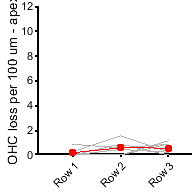

% number of OHC loss per row - Just P21

% this excludes P21 cochlea images with no OHC loss (mostly in apex)

apex1 = [0,0,0,0.86143774,0,0.259104277];
apex2 = [0.445072491,0.871753445,0,0.574291826,0,1.554625659];
apex3 = [0.222536246,0,0.876470279,0.86143774,1.134961057,0.259104277];

mid1 = [0.516996252,0.290527918,2.035854303,0.870046896,0.840962734,0.575927387,0.286442668,1.691458617,1.152355847,0.7146873,0];
mid2 = [0,0,0.581672658,2.030109423,1.401604557,1.151854774,1.145770674,1.933095563,1.440444809,1.191145501,0];
mid3 = [1.550988755,0.290527918,0.290836329,0.870046896,2.242567291,0.575927387,0.572885337,1.449821672,2.304711695,0.7146873,1.15314318];

base1 = [0.872590197,2.645914854,0,5.176773181,2.331872027,3.566449437,1.445738541,0.287828592];
base2 = [0,0.881971618,1.167559363,1.634770478,2.62335603,4.863340142,0.867443125,2.014800146];
base3 = [4.362950984,9.40769726,3.502678089,8.173852391,9.910456114,5.83600817,10.12016979,3.453943108];

conditions2 = {'Row 1','Row 2','Row 3'};
markSz = [1 20];
dim = [2 2];
color1 = 'r';
ylbl1 = ('OHC loss per 100 um - apex');
ylbl2 = ('OHC loss per 100 um - mid');
ylbl3 = ('OHC loss per 100 um - base');
figure
compare3(apex1,apex2,apex3,conditions2,ylbl1,dim,markSz,color1)
ylim([0 12]);

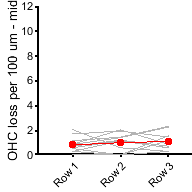

figure
compare3(mid1,mid2,mid3,conditions2,ylbl2,dim,markSz,color1)
ylim([0 12]);

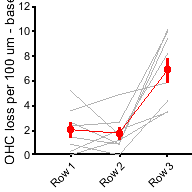

figure
compare3(base1,base2,base3,conditions2,ylbl3,dim,markSz,color1)
ylim([0 12])


% statistics?


% randomiation vs real distance between cells

apex1 = load('MAX_20200317 mouse 1 p21 tecta cre cx26flfl myo7a apex 25x_randomized'); % 3 cells 
apex2 = load('MAX_20200317 mouse 2 p21 tecta cre cx26flfl myo7a apex 25x_randomized'); % 3 cells
apex3 = load('MAX_20200317 mouse 3 p21 tecta cre cx26flfl myo7a apex 25x_randomized'); % 3 cells
apex4 = load('MAX_20200702 p21 tecta-cre cx26flfl myo7a mouse 3 apex 25x_randomized.mat'); % 8 cells
apex5 = load('C1-MAX_20200820 P21 tecta cre cx26flfl apex myo7a sox10 25x_randomized.mat'); % 4 cells

% mid1 = load('MAX_20200317 mouse 1 p21 tecta cre cx26flfl myo7a mid 25x_randomized'); % only two cells
mid2 = load('MAX_20200317 mouse 2 p21 tecta cre cx26flfl myo7a mid 25x_randomized'); % 10 cells lost
mid3 = load('MAX_20200317 mouse 3 p21 tecta cre cx26flfl myo7a mid 25x_randomized'); % example, 13 cells lost
mid4 = load('MAX_C3-20190729 p21 tecta cre cx26flfl dapi cx26 myo7a 25x flat mid_randomized'); % 8 cells lost
% mid5 = load('C3-MAX_20191018 p28 tecta cre cx26flfl dapi cx26 myo7a mid 25x_randomized.mat') % 3 cells lost
mid6 = load('MAX_20200702 p21 tecta-cre cx26flfl myo7a mouse 1 mid more basal 25x_randomized.mat');
mid7 = load('MAX_20200702 p21 tecta-cre cx26flfl myo7a mouse 2 mid 25x_randomized.mat');
mid8 = load('MAX_20200702 p21 tecta-cre cx26flfl myo7a mouse 3 mid 25x_randomized.mat');
mid9 = load('C1-MAX_20200820 P21 tecta cre cx26flfl mid myo7a sox10 25x_randomized.mat');
mid10 = load('C1-MAX_20200823 p21 tecta-cre cx26flfl cx26 myo7a mid 25x mouse 2_randomized.mat');

base1 = load('MAX_20200317 mouse 3 p21 tecta cre cx26flfl myo7a base 25x_randomized'); % 16 cells lost
base2 = load('MAX_C3-20191018 p28 tecta cre cx26flfl dapi cx26 myo7a base 25x_randomized'); % 16 cells lost

scaleS = 340.08/1024;

%minReal = [mean(apex2.minReal),mean(apex2.minReal),mean(apex3.minReal)]%,mean(mid2.minReal),mean(mid3.minReal),mean(mid4.minReal),mean(base1.minReal)];
%minRand = [mean(apex1.minRand),mean(apex2.minRand),mean(apex3.minRand)]%,mean(mid2.minRand),mean(mid3.minRand),mean(mid4.minRand),mean(base1.minRand)];

minReal2 = [apex1.minReal,apex2.minReal,apex3.minReal,apex4.minReal,apex5.minReal]*scaleS%,mid2.minReal,mid3.minReal,mid4.minReal,mid5.minReal,base1.minReal,base2.minReal]*scaleS;

minReal2 =     7.4021    7.4021    8.3467    8.9626    8.9626  152.1823    7.2498    7.2498  223.0691  215.6090   20.3174    9.9210    7.4021    8.3467    7.4021    8.3467   12.3179   12.4580   12.4580   24.3981   69.7267


minRand2 = [apex1.minRand,apex2.minRand,apex3.minRand,apex4.minRand,apex5.minRand]*scaleS%,mid2.minRand,mid3.minRand,mid4.minRand,mid5.minRand,base1.minRand,base2.minRand]*scaleS;

minRand2 =    55.8896   58.3877   55.8896  149.0285   75.0370   75.0370   90.1594   26.6959   26.6959   16.0890   16.0890   17.6703   40.9961   19.3066   19.3066   34.0054   17.6703  104.3268  140.6980  104.3268  140.6980


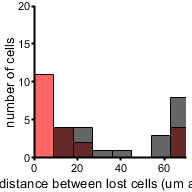

binY = [0 0.01:9:70 1000];
figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
xlabel('distance between lost cells (um apex)');
ylabel('number of cells');
figQuality(gcf,gca,[2 2])
xlim([0 70])
ylim([0 20]);


% normalized
figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Minimum distance between cells (um apex)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 70])
ylim([0 1]);
[h p] = kstest2(minReal2,minRand2);
p

p = 1.5676e-05

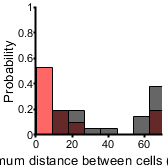

hold off

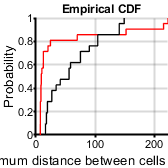


% CDF plot - only apex
figure
h1 = cdfplot(minReal2);
hold on
h2 = cdfplot(minRand2);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Minimum distance between cells (um apex)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])



% ylbl = ('Mean min distance to nearest lost cell');
% conditions = {'Real','Random'};
% dim = [1 2];
% compare2(minReal,minRand,conditions,ylbl,dim)
% ylim([0 400])
% 
% 
% ylbl = ('Min distance to nearest lost cell');
% conditions = {'Real','Random'};
% dim = [1 2];
% compare2_2(minReal2,minRand2,conditions,ylbl,dim)
% ylim([0 75])

% histogram 
% binY = [0 0.01:10:70 1000];
% figure;
% h1 = histogram(minReal2,'BinEdges',binY);
% xlabel('distance between lost cells (pixels)');
% ylabel('number of cells');
% figQuality(gcf,gca,[2.6 2.6])
% xlim([0 80])
% ylim([0 45]);
% figure;
% h2 = histogram(minRand2,'BinEdges',binY);
% h1.FaceColor = 'r';
% h2.FaceColor = 'k';
% %h1.BinWidth = 30;
% %h2.BinWidth = 30;
% %h1.Normalization = 'probability';
% %h2.Normalization = 'probability';
% xlabel('distance between lost cells');
% ylabel('number of cells');
% figQuality(gcf,gca,[2.6 2.6])
% xlim([0 80])
% ylim([0 45]);

% mid regions - more pronounced. 
minReal2 = [mid2.minReal,mid3.minReal,mid4.minReal,mid6.minReal,mid7.minReal,mid8.minReal,mid9.minReal,mid10.minReal]*scaleS

minReal2 =     7.5841    7.5841   30.9192   21.9989   21.9989   14.1711   25.5157   45.4092   22.2677   14.1711    7.1811    6.9352    7.4021    7.1291    7.7778    7.1291    6.9352    8.0442    7.4021   74.1217    7.1291    7.1291    8.0442    8.6958    8.6958  129.5714   19.3358   18.9275   18.9275   16.2111   11.3543   11.3543    9.6679    6.0164    8.4647    7.3517    7.4021    8.4647    6.0164   10.0821   10.0821   10.5625    7.0417    7.4021    8.5230    7.3517    7.6167    7.4854    6.4921    6.4921


minRand2 = [mid3.minRand,mid3.minRand,mid4.minRand,mid6.minRand,mid7.minRand,mid8.minRand,mid9.minRand,mid10.minRand]*scaleS

minRand2 =    14.2783   14.2783   13.7712   62.8462   13.7712   14.5897   13.7135   39.0112   37.8765   13.7281   13.7135   29.0763   43.3855   14.2783   14.2783   13.7712   62.8462   13.7712   14.5897   13.7135   39.0112   37.8765   13.7281   13.7135   29.0763   43.3855    7.7694   50.0242   13.9174   42.1035   50.0242   13.9174    7.7694   20.5577   92.8788    6.6887    7.2674   14.9548    6.6887    6.6887   27.0265   13.3236   14.9548   27.0265   25.9710   13.3236    6.6887   41.4388   38.5901   16.5943


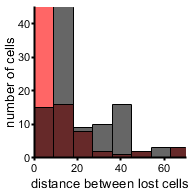


figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
xlabel('distance between lost cells');
ylabel('number of cells');
figQuality(gcf,gca,[2 2])
xlim([0 70])
ylim([0 45]);

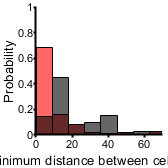


% normalized
figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Minimum distance between cells (um)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 70])
ylim([0 1]);

[h p] = kstest2(minReal2,minRand2);
p

p = 8.0319e-16

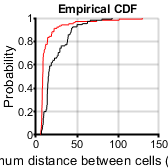

%print(gcf,'-dpdf')

% CDF plot - only mid
figure
h1 = cdfplot(minReal2);
hold on
h2 = cdfplot(minRand2);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Minimum distance between cells (um apex)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])

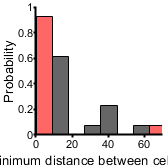


% representative example - from mid
figure
h1 = histogram(mid3.minReal*scaleS,'BinEdges',binY);
hold on
h2 = histogram(mid3.minRand*scaleS,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Minimum distance between cells (um)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 70])
ylim([0 1]);

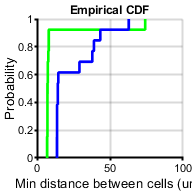

%print(gcf,'-dpdf')

% Representative example - same as above

figure
h1 = cdfplot(mid3.minReal*scaleS);
hold on
h2 = cdfplot(mid3.minRand*scaleS);
h1.Color = 'g';
h2.Color = 'b';
h1.LineWidth = 2;
h2.LineWidth = 2;
xlabel('Min distance between cells (um)');
ylabel('Probability');
figQuality(gcf,gca,[2 2])
xlim([0 100])


% mid/apex combined - earlier cell loss
minReal2 = [apex1.minReal,apex2.minReal,apex3.minReal,apex4.minReal,mid2.minReal,mid3.minReal,mid4.minReal,mid6.minReal,mid7.minReal,mid8.minReal]*scaleS

minReal2 =     7.4021    7.4021    8.3467    8.9626    8.9626  152.1823    7.2498    7.2498  223.0691  215.6090   20.3174    9.9210    7.4021    8.3467    7.4021    8.3467   12.3179    7.5841    7.5841   30.9192   21.9989   21.9989   14.1711   25.5157   45.4092   22.2677   14.1711    7.1811    6.9352    7.4021    7.1291    7.7778    7.1291    6.9352    8.0442    7.4021   74.1217    7.1291    7.1291    8.0442    8.6958    8.6958  129.5714   19.3358   18.9275   18.9275   16.2111   11.3543   11.3543    9.6679


minRand2 = [apex1.minRand,apex2.minRand,apex3.minRand,apex4.minRand,mid3.minRand,mid3.minRand,mid4.minRand,mid6.minRand,mid7.minRand,mid8.minRand]*scaleS

minRand2 =    55.8896   58.3877   55.8896  149.0285   75.0370   75.0370   90.1594   26.6959   26.6959   16.0890   16.0890   17.6703   40.9961   19.3066   19.3066   34.0054   17.6703   14.2783   14.2783   13.7712   62.8462   13.7712   14.5897   13.7135   39.0112   37.8765   13.7281   13.7135   29.0763   43.3855   14.2783   14.2783   13.7712   62.8462   13.7712   14.5897   13.7135   39.0112   37.8765   13.7281   13.7135   29.0763   43.3855    7.7694   50.0242   13.9174   42.1035   50.0242   13.9174    7.7694


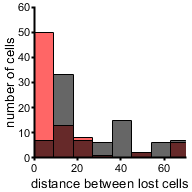


figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
xlabel('distance between lost cells');
ylabel('number of cells');
figQuality(gcf,gca,[2 2])
xlim([0 70])
ylim([0 60]);

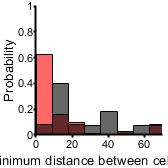


% normalized
figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Minimum distance between cells (um)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 70])
ylim([0 1]);

[h p] = kstest2(minReal2,minRand2);
p

p = 1.8424e-14

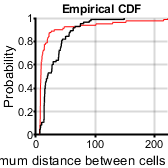

%print(gcf,'-dpdf')

% CDF plot - combined mid/apex
figure
h1 = cdfplot(minReal2);
hold on
h2 = cdfplot(minRand2);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Minimum distance between cells (um apex)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])


% base - tougher b/c of SNR, more cells lost
minReal2 = [base1.minReal,base2.minReal]*scaleS

minReal2 =     5.9958    5.9751    7.7937    6.0575    5.9958   33.3644    6.0575   65.9158    7.7937    8.4647   17.6815   10.0081   10.0081    5.9751    8.6958    9.6679    7.7937    7.1811    7.1811    7.6167   28.4513    6.2389    6.2389    7.9667    7.4854    7.9667    7.4854   22.9530


minRand2 = [base1.minRand,base2.minRand]*scaleS

minRand2 =     6.4653   12.2286   17.2327   26.7061    6.7957   12.2286   22.6427    6.5759   69.0729    6.7957   22.6427    6.4653   22.6427    7.4510   27.5350    6.5759    7.8369    7.0106   34.4180   11.8320   15.4190    7.0106    7.8369   11.8320    7.7272   34.4180    7.7272    8.0731


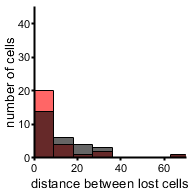


figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
xlabel('distance between lost cells');
ylabel('number of cells');
figQuality(gcf,gca,[2 2])
xlim([0 70])
ylim([0 45]);

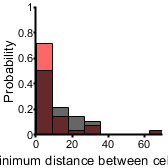


% normalized
figure
h1 = histogram(minReal2,'BinEdges',binY);
hold on
h2 = histogram(minRand2,'BinEdges',binY);
h1.FaceColor = 'r';
h2.FaceColor = 'k';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Minimum distance between cells (um)');
ylabel('Probability');
figQuality(gcf,gca,[1.75 1.75])
xlim([0 70])
ylim([0 1]);

[h p] = kstest2(minReal2,minRand2);
p

p = 0.0876

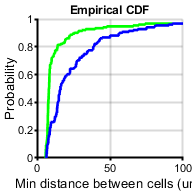

%print(gcf,'-dpdf')

% all together
minReal2 = [apex1.minReal,apex2.minReal,apex3.minReal,apex4.minReal,apex5.minReal,mid2.minReal,mid3.minReal,mid4.minReal,mid6.minReal,mid7.minReal,mid8.minReal,mid9.minReal,mid10.minReal,base1.minReal,base2.minReal]*scaleS;
minRand2 = [apex1.minRand,apex2.minRand,apex3.minRand,apex4.minRand,apex5.minRand,mid2.minRand,mid3.minRand,mid4.minRand,mid6.minRand,mid7.minRand,mid8.minRand,mid9.minRand,mid10.minRand,base1.minRand,base2.minRand]*scaleS;
figure
h1 = cdfplot(minReal2);
hold on
h2 = cdfplot(minRand2);
h1.Color = 'g';
h2.Color = 'b';
h1.LineWidth = 2;
h2.LineWidth = 2;
xlabel('Min distance between cells (um)');
ylabel('Probability');
xlim([0 100])
figQuality(gcf,gca,[2 2])

[h p] = kstest2(minReal2,minRand2);
p

p = 4.2177e-17